# Course 3. Example 3.4: D-LQR

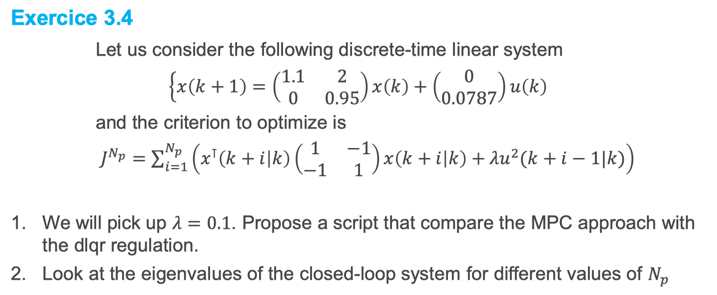

### Initialisation

clear;
close all;
clc;

#### **Q1: System Definition and Model prediction**

% System definition
A=[1.1 2 ;0 0.95];
B=[0; 0.0787];
nx=size(A,2);
nu=size(B,2);

% Model prediction
Np=10;
F=zeros(Np*nx,nx);
H=zeros(Np*nx,Np*nu);

for i=1:Np
    F(nx*(i-1)+1:nx*i,:)=A^i ;
    for j=1:i
        H(nx*(i-1)+1:nx*i,nu*(j-1)+1:nu*j)=A^(i-j)*B;
    end
end


#### Q2: Objective function and Feedback Control

% Objective function
lambda=0.1;

Q = [1 -1; -1 1];
% Warning: Your Hessian is not symmetric. 
% Resetting H=(H+H')/2.
R = lambda;

Qx=zeros(nx*Np);
Ru=zeros(nu*Np);

for i =1:Np
    Qx(nx*(i-1)+1:nx*i,nx*(i-1)+1:nx*i)=Q;
    Ru(nu*(i-1)+1:nu*i,nu*(i-1)+1:nu*i)=R;
end

#### Q3: MPC Optimal feedback (off-line computation)

First=zeros(nu,nu*Np);
First(nu,nu)=eye(nu);
K_Np=First*(H'*Qx*H+Ru)^(-1)*H'*Qx*F;

#### Q3: Closed-loop implementation: MPC approach

Use quadprog to determine the optimal input sequence using U(K|k) as the optimization variable.

Nsimu=10;
xinit=[1;1];
xk=xinit;
H_quad = 2*(H'*Qx*H + Ru); % indenpendent from k
X1 = [];
for i=1:Nsimu
    X1 = [X1 xk];
    f_quad = 2*H'*Qx*F*xk;
    [Uopt,Jopt] = quadprog(H_quad,f_quad);
    uk=First*Uopt; %optimal control
    xkp1=A*xk+B*uk;
    xk=xkp1;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



X1

X1 =     1.0000    3.1000    2.8811    1.9666    1.0918    0.4858    0.1452   -0.0088   -0.0567   -0.0558
    1.0000   -0.2645   -0.6013   -0.5357   -0.3576   -0.1946   -0.0843   -0.0235    0.0033    0.0111


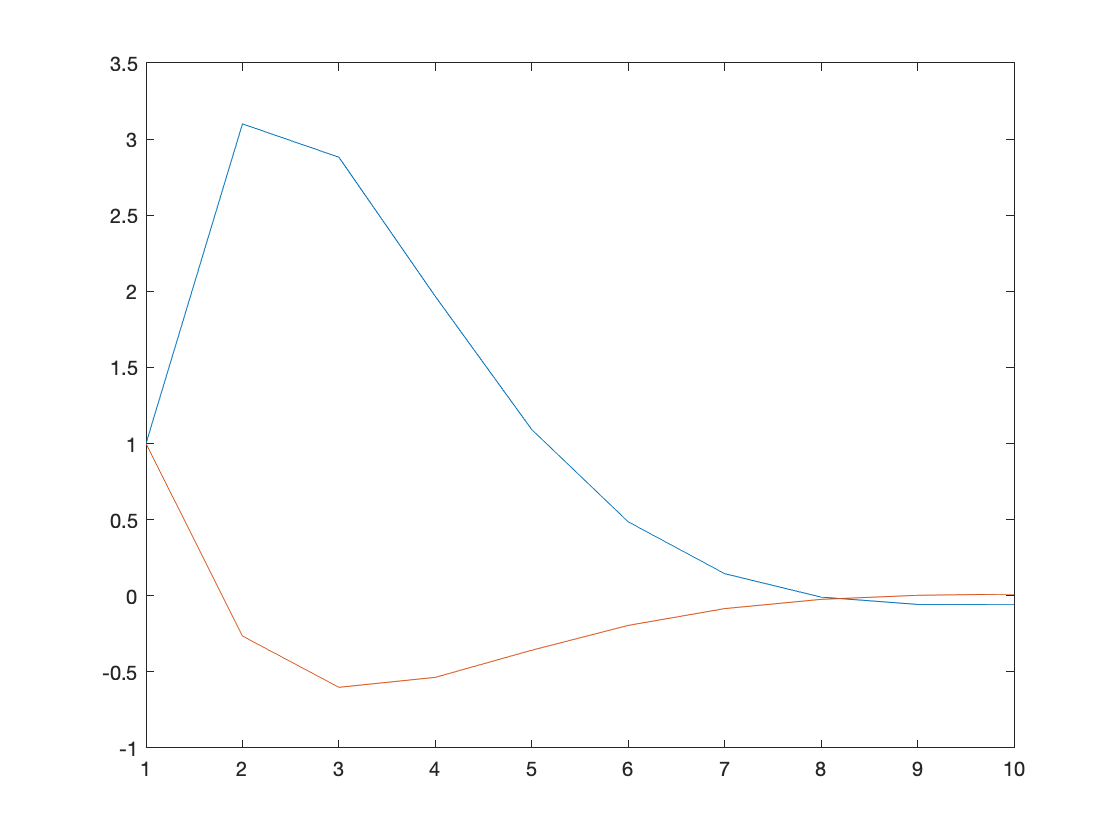

plot(1:Nsimu,X1);

#### Analysis of the closed-loop system

eigenvalues=eig(A-B*K_Np);
norm(eigenvalues(1),1)

ans = 0.5723

#### Q4： Try another configuration for the optimization: D-LQR regulation

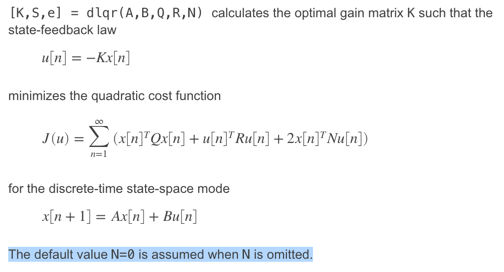

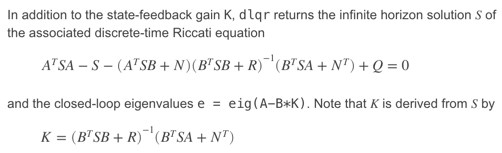

% A, B, Q, R are the same
% defaut value N = 0, since there is no term of type x(k)*u(k)
[Klqr,P,eigenvals] = dlqr(A,B,Q,R);
% P = Riccati_equation_solution

#### Analysis

Eigenvaluesdlqr=eig(A-B*Klqr)

Eigenvaluesdlqr =    0.5174 + 0.2443i
   0.5174 - 0.2443i


EigenvaluesMPC_Np=eig(A-B*K_Np)

EigenvaluesMPC_Np =    0.5175 + 0.2444i
   0.5175 - 0.2444i


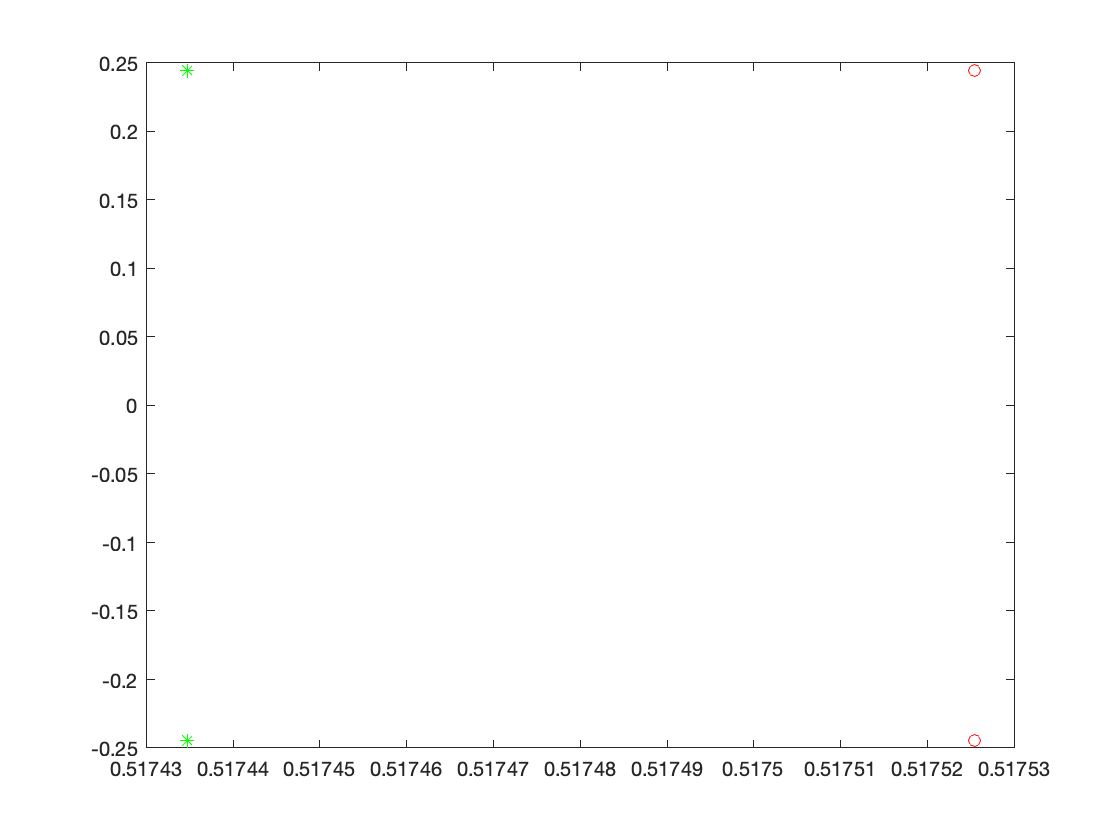


EigdlqrReal=real(Eigenvaluesdlqr);
EigdlqrImag=imag(Eigenvaluesdlqr);
EigMPC_NpReal=real(EigenvaluesMPC_Np);
EigMPC_NpImag=imag(EigenvaluesMPC_Np);

figure
plot(EigdlqrReal,EigdlqrImag,'g*')
hold on
plot(EigMPC_NpReal,EigMPC_NpImag,'ro')

####